# Setup

clc
clear
warning('off')

%Input signals

%Position Input
N_temp = 534; %TODO: Increase time to match Land (issues with stitching chirp)
delta_t = 0.01;
t = 0:delta_t:2*N_temp*delta_t;
NT = 2*N_temp;
t1 = 0:delta_t:N_temp*delta_t;
I_p(1:N_temp+1) = 1-chirp(t1,0.5,N_temp*delta_t,1);
I_p(N_temp+1:2*N_temp+1) = 1-chirp(t1,1,N_temp*delta_t,3);

%Velocity Input
I_v = diff(I_p)/delta_t;

%Time Alignment
I_p = I_p(1:NT);
t = t(1:NT);

%Concatenate Time Series
P_in = [t;I_p]';
V_in = [t;I_v]';


# "G" Model

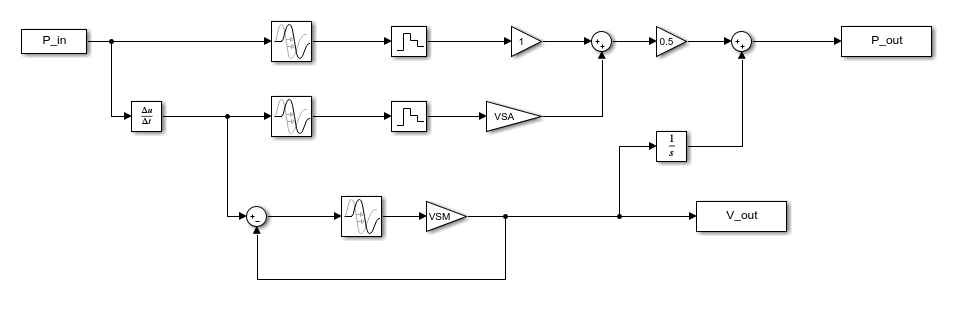

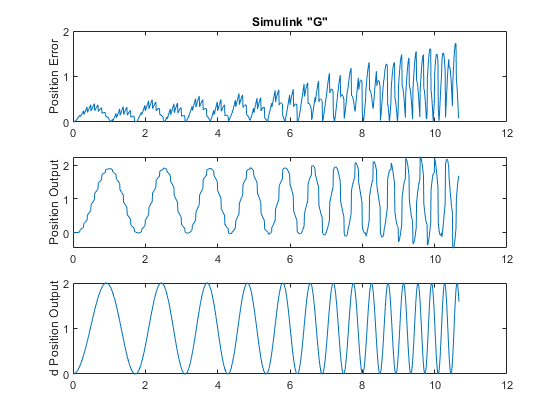

%Model "g"
%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'g';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
VSA = 0.05;
VSM = 0.8;

%Delay and zero-order hold time
delay = 0.1;

%Simulate
out = sim('g.slx');

%Outputs
g_pout = P_out;
g_vout = V_out;

%Position Error
g_error = abs(g_pout-P_in(:,2));

figure
subplot(3,1,1)
plot(t,g_error)
ylabel('Position Error')
title('Simulink "G"')
subplot(3,1,2)
plot(t,g_pout)
ylabel('Position Output')
subplot(3,1,3)
plot(t,I_p)
ylabel('d Position Output')

This is the result using the original "G" model developed by Yi.  This model fairly closely matches Land's implementation.

# Smooth TF model: Pure Delay

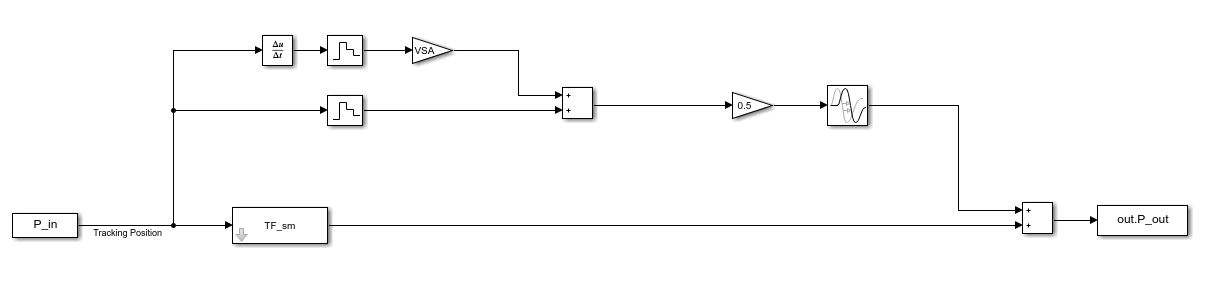

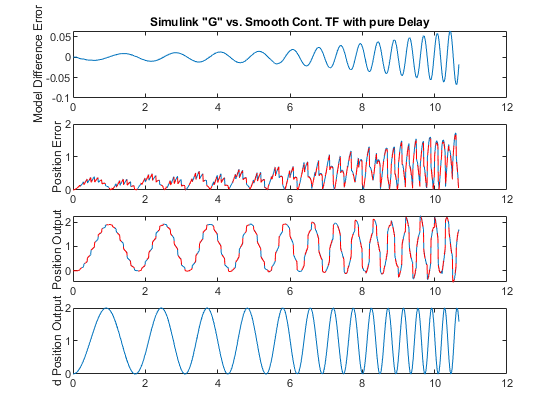

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (position)
PD = tf([K_D K_P],[1 0]);

%Pade Approximation
s = tf('s');
sys = exp(-d*s);
delayPade = pade(sys,2);

%G(s)
G = PD*sys;

%Feedback
TF_sm = G/(1+G);

%Simulate
out = sim('HybridModel.slx');

%Outputs
stfe_pout = out.P_out;

%Position Error
stfe_error = abs(stfe_pout-P_in(:,2));

figure
subplot(4,1,1)
plot(t,g_pout-stfe_pout)
title('Simulink "G" vs. Smooth Cont. TF with pure Delay')
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,g_error,t,stfe_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfe_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

We can see that the use of the pure form of the time delay as a premultiplier to the PD transfer function of exp(-d*s) results in a close match of the simulink model.  This is likely? due to the fact that MATLAB encodes these delays into the state space representation of the transfer function.

# Smooth TF model: Pade Approximation

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (position)
PD = tf([K_D K_P],[1 0]);

%Pade Approximation
s = tf('s');
sys = exp(-d*s);
delayPade = pade(sys,2)

delayPade =
 
  s^2 - 60 s + 1200
  -----------------
  s^2 + 60 s + 1200
 
Continuous-time transfer function.



Approximations of order > 2 result in singularities in the lti system, so a Pade Approximation of order 2 is the closest match. 


%G(s)
G = PD*delayPade;%sys;

%Feedback
TF_sm = G/(1+G)

TF_sm =
 
                                           
           0.8 s^6 - 960 s^4 + 1.152e06 s^2
                                           
  ---------------------------------------------------
                                                     
  1.8 s^6 + 120 s^5 + 5040 s^4 + 144000 s^3          
                                                     
                                       + 2.592e06 s^2
                                                     
 
Continuous-time transfer function.



This is the closed loop transfer function for the smooth (PD) feedback loop with a Pade approximation for the delay.

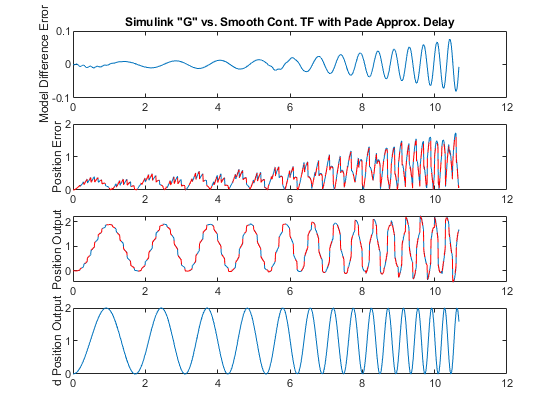


%Simulate
out = sim('HybridModel.slx');

%Outputs
stf_pout = out.P_out;

%Position Error
stf_error = abs(stf_pout-P_in(:,2));

figure
subplot(4,1,1)
plot(t,g_pout-stf_pout)
title('Simulink "G" vs. Smooth Cont. TF with Pade Approx. Delay')
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,g_error,t,stf_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stf_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

 The 2nd order Pade approximation for the delay results in a larger deviation from the simulink model (~2x the pure delay at higher frequencies).

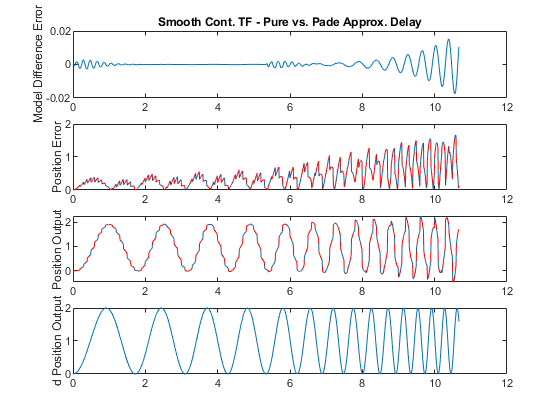

figure
subplot(4,1,1)
plot(t,stfe_pout-stf_pout)
title('Smooth Cont. TF - Pure vs. Pade Approx. Delay')
ylabel('Model Difference Error')
subplot(4,1,2)
plot(t,stfe_error,t,stf_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,stfe_pout,t,stf_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

# Smooth TF model: Discrete

We can recover the better matching of the pure delay by moving the smooth transfer function into the z-domain, with a sample rate equal to the inverse of the delta-t of the input array (this mimics a continuous system).  In the z-domain, a delay is just a factor of z^(-Td/Ts), where Ts is the sample time, and Td is the delay time.  For example, with a sample time Ts = 0.01s, and a delay time Td = 0.1s, the z-domain delay becomes z^(-10).  This factor of z is pre-multiplied to the z-transformed PD transfer function to yield a discrete time representation of the delayed PD system for the smooth action.

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t)

tfz =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.



z_delay = tfz^(-d/delta_t)

z_delay =
 
   1
  ----
  z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.



This is the z-delay.

G_d = z_delay*PD_d;

%TF for PD feedback
TF_sm = G_d/(1+G_d)

TF_sm =
 
     0.8 z^10
  ---------------
  z^20 + 0.8 z^10
 
Sample time: 0.01 seconds
Discrete-time transfer function.



This is the discrete form of the delayed smooth action PD feedback loop.

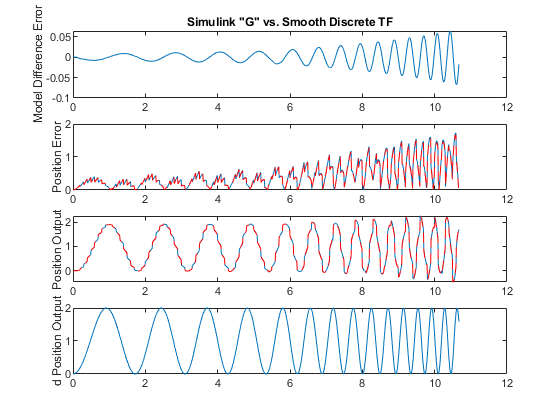

%Simulate
out = sim('HybridModel.slx');

%Outputs
stfd_pout = out.P_out;

%Position Error
stfd_error = abs(stfd_pout-P_in(:,2));

figure
subplot(4,1,1)
plot(t,g_pout-stfd_pout)
ylabel('Model Difference Error')
title('Simulink "G" vs. Smooth Discrete TF')
subplot(4,1,2)
plot(t,g_error,t,stfd_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfd_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

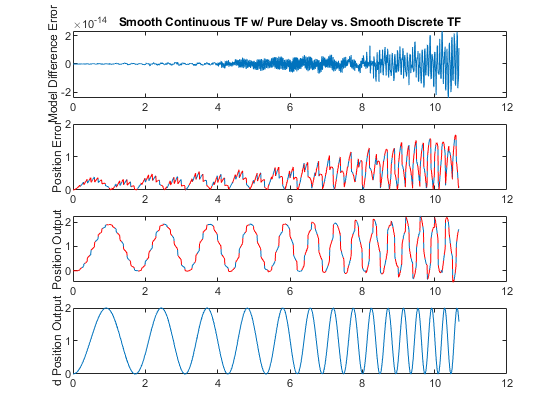


figure
subplot(4,1,1)
plot(t,stfe_pout-stfd_pout)
ylabel('Model Difference Error')
title('Smooth Continuous TF w/ Pure Delay vs. Smooth Discrete TF')
subplot(4,1,2)
plot(t,stfe_error,t,stfd_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,stfe_pout,t,stfd_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

We can see that we recovered the performance of the pure delay system,  but in a compact z-domain transfer function.  This is the transfer function we will use moving forward for the smooth PD feedback loop.

# Hybrid Model: Discrete Smooth PD TF + Discretized Saccades

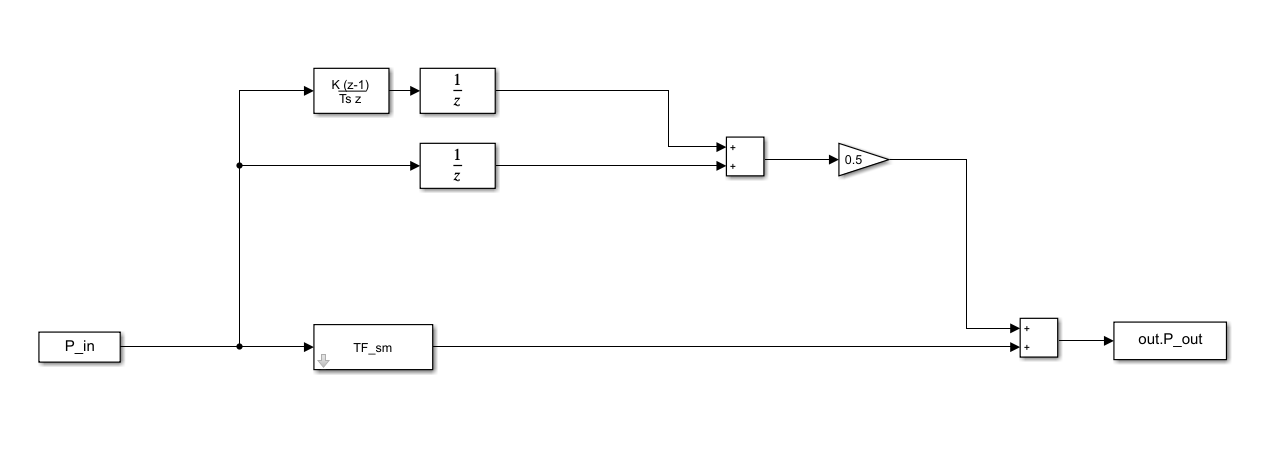

The saccade motions are a more complex scenario because they incorporate zero-order holds at the delay rate - in other words, their output remains the same for the duration of the delay period.  This can be modeled in the discrete domain by a discrete transfer function *with a sample rate equal to the delay period*.  In other words, the nature of the zero order hold is a z transform of 1 because it forms the basis of the discrete transfer function.  Therefore, the saccade portion because a simple combination of two signal paths - a delayed velocity path with a gain of VSA, and a delayed position path with unity gain.  The delays are represented by factors of 1/z because the delay time equals the sample time for this leg of the system.

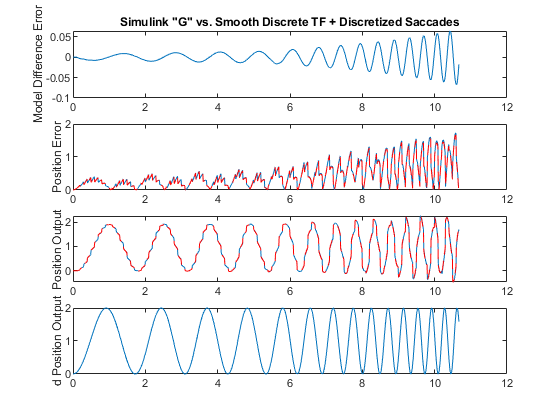

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel1';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t);
z_delay = tfz^(-10);
G_d = z_delay*PD_d;

%TF for PD feedback
TF_sm = G_d/(1+G_d);

%Simulate
out = sim('HybridModel1.slx');

%Outputs
stfds_pout = out.P_out;

%Position Error
stfds_error = abs(stfds_pout-P_in(:,2));
figure
subplot(4,1,1)
plot(t,g_pout-stfds_pout)
ylabel('Model Difference Error')
title('Simulink "G" vs. Smooth Discrete TF + Discretized Saccades')
subplot(4,1,2)
plot(t,g_error,t,stfds_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfds_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

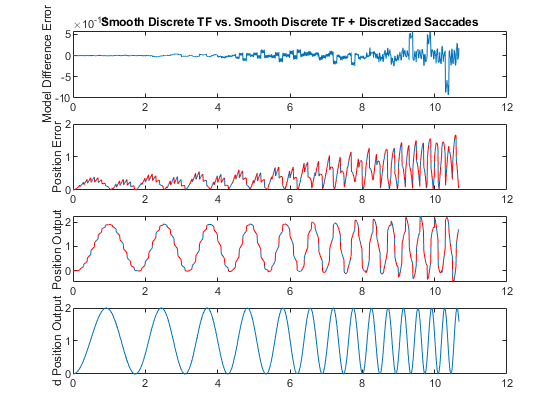


figure
subplot(4,1,1)
plot(t,stfe_pout-stfds_pout)
ylabel('Model Difference Error')
title('Smooth Discrete TF vs. Smooth Discrete TF + Discretized Saccades')
subplot(4,1,2)
plot(t,stfe_error,t,stfds_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,stfe_pout,t,stfds_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

When we simulate this, we get the same results as simulating with the zero order hold and delay blocks in simulink (Smooth Discrete TF simulation)

# Hybrid Model: Discrete Smooth PD TF + Discrete Saccade TF

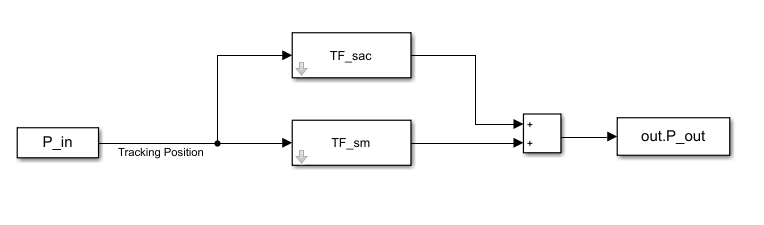

The next logical step for producing an overall system transfer function is to reduce the saccade system to a single z-domain transfer function.  This seems to be trivial - but I am having issues getting the result to match the results from the expanded version.  I believe it has something to do with the derivative block - I'm not sure how simulink is treating that block.

%Simulink options
tend = num2str(t(end));
stepsize = num2str(delta_t);
simName = 'HybridModel2';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

%Gains
K_P = 0;
K_D = 0.8;
VSA = 0.05;

%Delay and zero-order hold time
d = 0.1;

%PD System w/ integrator (continuous)
PD = tf([K_D K_P],[1 0]);

%To discrete
PD_d = c2d(PD,delta_t,'foh');

%Add delay
tfz = tf('z',delta_t);
z_delay = tfz^(-10);
G_d = z_delay*PD_d;

%TF for PD feedback
TF_sm = G_d/(1+G_d);

%Discrete Saccades
tfzd = tf('z',delay);
tf_sv = VSA*2*(tfzd-1)/(delay*tfzd*(tfzd+1))

tf_sv =
 
    0.1 z - 0.1
  ---------------
  0.1 z^2 + 0.1 z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



This is the derivative leg of the saccade.  It is formulated using a tustin transform for s->z.  This gives better results (closer to the G simulation) then using the formula actually listed on the simulink block, which I believe is a forward Euler.  I need to do a little more reading on this to close in on the same performance as the expanded block diagram.

tf_sp = 1/tfzd

tf_sp =
 
  1
  -
  z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



This is the position leg of the saccade.  It is just a sample delay with unity gain.

TF_sac = 0.5*(tf_sv+tf_sp)

TF_sac =
 
       0.1 z^2
  -----------------
  0.1 z^3 + 0.1 z^2
 
Sample time: 0.1 seconds
Discrete-time transfer function.



This is the combined discrete transfer function for the saccade portion of the system.  Note that this has a different sample time than the smooth portion, which is pseudo continuous (sampled at the frequency of the input signal, no signal loss).

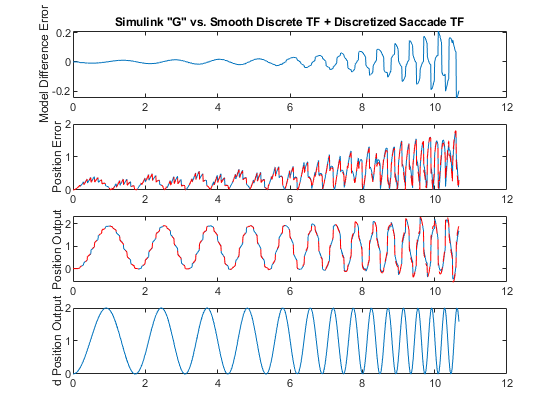

%Simulate
out = sim('HybridModel2.slx');

%Outputs
stfdss_pout = out.P_out;

%Position Error
stfdss_error = abs(stfdss_pout-P_in(:,2));

figure
subplot(4,1,1)
plot(t,g_pout-stfdss_pout)
ylabel('Model Difference Error')
title('Simulink "G" vs. Smooth Discrete TF + Discretized Saccade TF')
subplot(4,1,2)
plot(t,g_error,t,stfdss_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,g_pout,t,stfdss_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

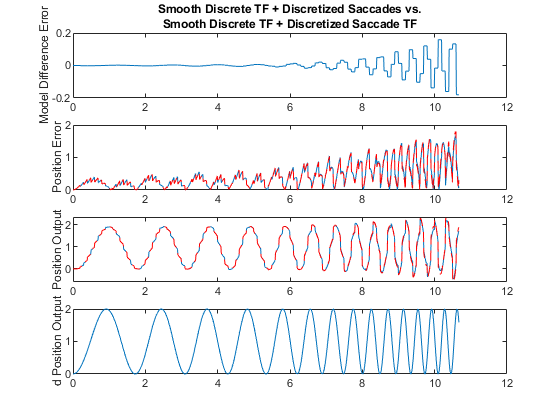


figure
subplot(4,1,1)
plot(t,stfds_pout-stfdss_pout)
ylabel('Model Difference Error')
title({'Smooth Discrete TF + Discretized Saccades vs.','Smooth Discrete TF + Discretized Saccade TF'})
subplot(4,1,2)
plot(t,stfds_error,t,stfdss_error,'--r')
ylabel('Position Error')
subplot(4,1,3)
plot(t,stfds_pout,t,stfdss_pout,'--r')
ylabel('Position Output')
subplot(4,1,4)
plot(t,I_p)
ylabel('d Position Output')

I believe the different performance between the TF version of the saccades and the expanded block diagram version has something to do with the simulink implementation of the derivative block.  As mentioned, I'd like to investigate this more, but this still provides a reasonably close fit to the results of the Land style model.

# Summary

What we end up with in the end is two parallel linear systems.  Both are discrete transfer functions.  However, combining them into one linear transfer function between P_out and P_in is not possible in the current state because they have different sample rates.  I made an effort to move them back into the s-domain, but doing so results in non-causal transfer functions - which I'd like to investigate further.  Likely it has to do with the loss of information with respect to the zero order hold blocks.

So this raises an interesting question for stability analysis.  The two systems are linear in z - can we examine the stability envelope of each individually, and declare that overall system stability is the overlap of the two individual stability envelopes?  My intuition says yes, but I haven't put pen to paper yet to develop the mathematical rigor to prove it.